**Example 8.11** A One-half fraction for the plasma etch experiment, $2^{4-1}$ design

10/11/21 21:29 @ FH

Objective: To replicate the analysis from the textbook example, to translate the analysis procedure to HW3_Solutions Problem 8.2-3 with the Fractional Replication twist.[l](https://www.mathworks.com/help/stats/fractional-factorial-designs.html)

a. Choose basic factors and generators

To find a design that achieves a specified resolution - this is a way to catalog fractional factorial designs according to the alias pattern they produce. 

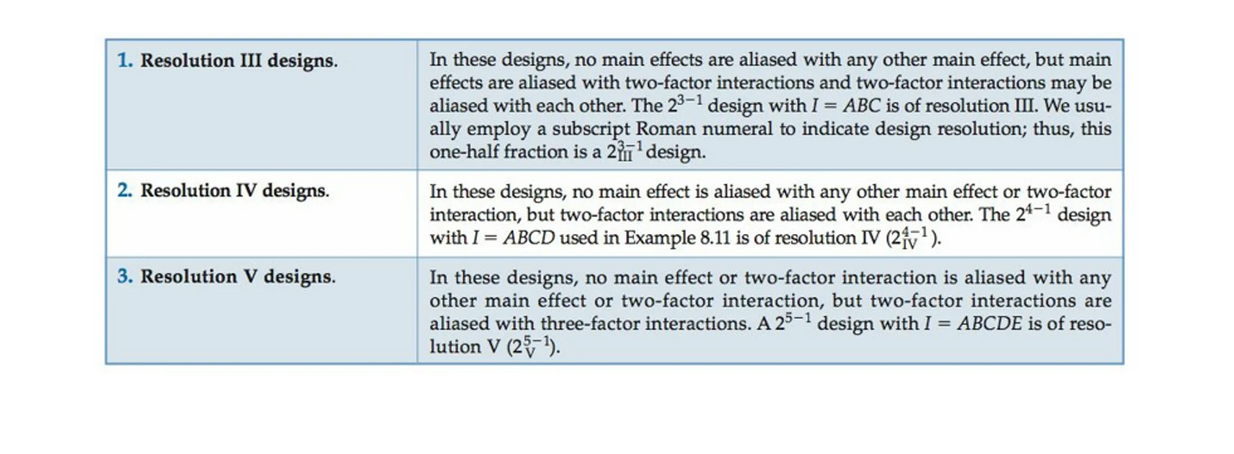

imshow('DesignResolution.png')

in a specified number of runs; use the function `fracfactgen`

generators = fracfactgen('a b c d',3,4) % These are generators for 

generators = 4×1 cell array
    {'a'  }
    {'b'  }
    {'c'  }
    {'abc'}


% a four-factor design with factors a, b, c, and d, using 2^3 = 8 runs
% to achieve resolution IV.

b. Fractional factorial design

This design is constructed by writing down a $2^3$ in the factors A (gap), B (pressure), C (flow rate), and then setting D (power setting) = ABC.

[dfF,confounding] = fracfact(generators) % This is a two factor design in which two 

dfF =     -1    -1    -1    -1
    -1    -1     1     1
    -1     1    -1     1
    -1     1     1    -1
     1    -1    -1     1
     1    -1     1    -1
     1     1    -1    -1
     1     1     1     1


confounding = 11×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'  }
    {'X1'   }    {'a'        }    {'X1'           }
    {'X2'   }    {'b'        }    {'X2'           }
    {'X3'   }    {'c'        }    {'X3'           }
    {'X4'   }    {'abc'      }    {'X4'           }
    {'X1*X2'}    {'ab'       }    {'X1*X2 + X3*X4'}
    {'X1*X3'}    {'ac'       }    {'X1*X3 + X2*X4'}
    {'X1*X4'}    {'bc'       }    {'X1*X4 + X2*X3'}
    {'X2*X3'}    {'bc'       }    {'X1*X4 + X2*X3'}
    {'X2*X4'}    {'ac'       }    {'X1*X3 + X2*X4'}
    {'X3*X4'}    {'ab'       }    {'X1*X2 + X3*X4'}


% two-level basic factors are measured in every combination of levels,
% while the remaining factor (c) is measured only at levels defined
% by the generator ab.

The resulting design from `dfF `has the defining relation *I = ABCD.*

An optional output from `fracfact` displays the *confounding pattern *of the design, `confounding.`

Here we see that the fractional factorials represent 

The 'Confounding' column represents the **sequence** of the fractional factorial design used to estimate the effect - i.e., the 'Term' column. 

c. Create a table to hold the DOE test matrix and the response data that corresponds to the runs in the fraction. The table will be concatenated for the two replicates.

etchRate = [550;1075;1052;601;749;642;650;729]; % Replicate 1, corresponding to runs from dfF
%tlife2c = [453;348;435;419]; % Replicate 2
tbl = table([dfF(:,1)],[dfF(:,2)],[dfF(:,3)],[dfF(:,4)],[etchRate],'VariableNames',{'A','B','C','D','EtchRate'})

tbl = 8×5 table
    A     B     C     D     EtchRate
    __    __    __    __    ________

    -1    -1    -1    -1       550  
    -1    -1     1     1      1075  
    -1     1    -1     1      1052  
    -1     1     1    -1       601  
     1    -1    -1     1       749  
     1    -1     1    -1       642  
     1     1    -1    -1       650  
     1     1     1     1       729  


d. Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

% *** 10/11/21 21:53 -- edit this...
mdlc = fitlm(tbl,'EtchRate ~ A + B + C + D')

mdlc = Linear regression model:
    EtchRate ~ 1 + A + B + C + D

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)        756     57.559      13.134    0.00095336
    A                -63.5     57.559     -1.1032       0.35049
    B                    2     57.559    0.034747       0.97446
    C                 5.75     57.559    0.099897       0.92673
    D               145.25     57.559      2.5235      0.085913


Number of observations: 8, Error degrees of freedom: 3
Root Mean Squared Error: 163
R-squared: 0.717,  Adjusted R-Squared: 0.339
F-statistic vs. constant model: 1.9, p-value = 0.313

% Since two-way factor interactions are confounded with each other, only
% the below interactions need be included in the model.
mdl2 = addTerms(mdlc,'A*B')

mdl2 = Linear regression model:
    EtchRate ~ 1 + C + D + A*B

Estimated Coefficients:
                   Estimate      SE        tStat       pValue 
                   ________    ______    _________    ________

    (Intercept)        756     70.406       10.738    0.008562
    A                -63.5     70.406     -0.90191      0.4623
    B                    2     70.406     0.028407     0.97992
    C                 5.75     70.406     0.081669     0.94235
    D               145.25     70.406        2.063     0.17519
    A:B                 -5     70.406    -0.071016     0.94985


Number of observations: 8, Error degrees of freedom: 2
Root Mean Squared Error: 199
R-squared: 0.718,  Adjusted R-Squared: 0.0116
F-statistic vs. constant model: 1.02,

mdl3 = addTerms(mdl2,'A*C')

mdl3 = Linear regression model:
    EtchRate ~ 1 + D + A*B + A*C

Estimated Coefficients:
                   Estimate     SE        tStat       pValue 
                   ________    _____    _________    ________

    (Intercept)        756     98.75       7.6557    0.082688
    A                -63.5     98.75     -0.64304     0.63619
    B                    2     98.75     0.020253     0.98711
    C                 5.75     98.75     0.058228     0.96297
    D               145.25     98.75       1.4709     0.38011
    A:B                 -5     98.75    -0.050633     0.96779
    A:C             -12.75     98.75     -0.12911     0.91826


Number of observations: 8, Error degrees of freedom: 1
Root Mean Squared Error: 279
R-squared:

mdl4 = addTerms(mdl3,'A*D') % Note that after adding this term, the output 

mdl4 = Linear regression model:
    EtchRate ~ 1 + A*B + A*C + A*D

Estimated Coefficients:
                   Estimate    SE    tStat    pValue
                   ________    __    _____    ______

    (Intercept)        756     0      Inf      NaN  
    A                -63.5     0     -Inf      NaN  
    B                    2     0      Inf      NaN  
    C                 5.75     0      Inf      NaN  
    D               145.25     0      Inf      NaN  
    A:B                 -5     0     -Inf      NaN  
    A:C             -12.75     0     -Inf      NaN  
    A:D             -98.75     0     -Inf      NaN  


Number of observations: 8, Error degrees of freedom: 0
R-squared: 1,  Adjusted R-Squared: NaN
F-statist

% model statistics show zero -- not sure why?
% Now I know why -- see HW3_Solutions.mlx, 'Singularity.'

The model estimates (i.e., the effects), which is the regression coefficient column x 2, agree with the full factorial results in Example 8.9.

e. Plot of the whole model, except the intercept term.

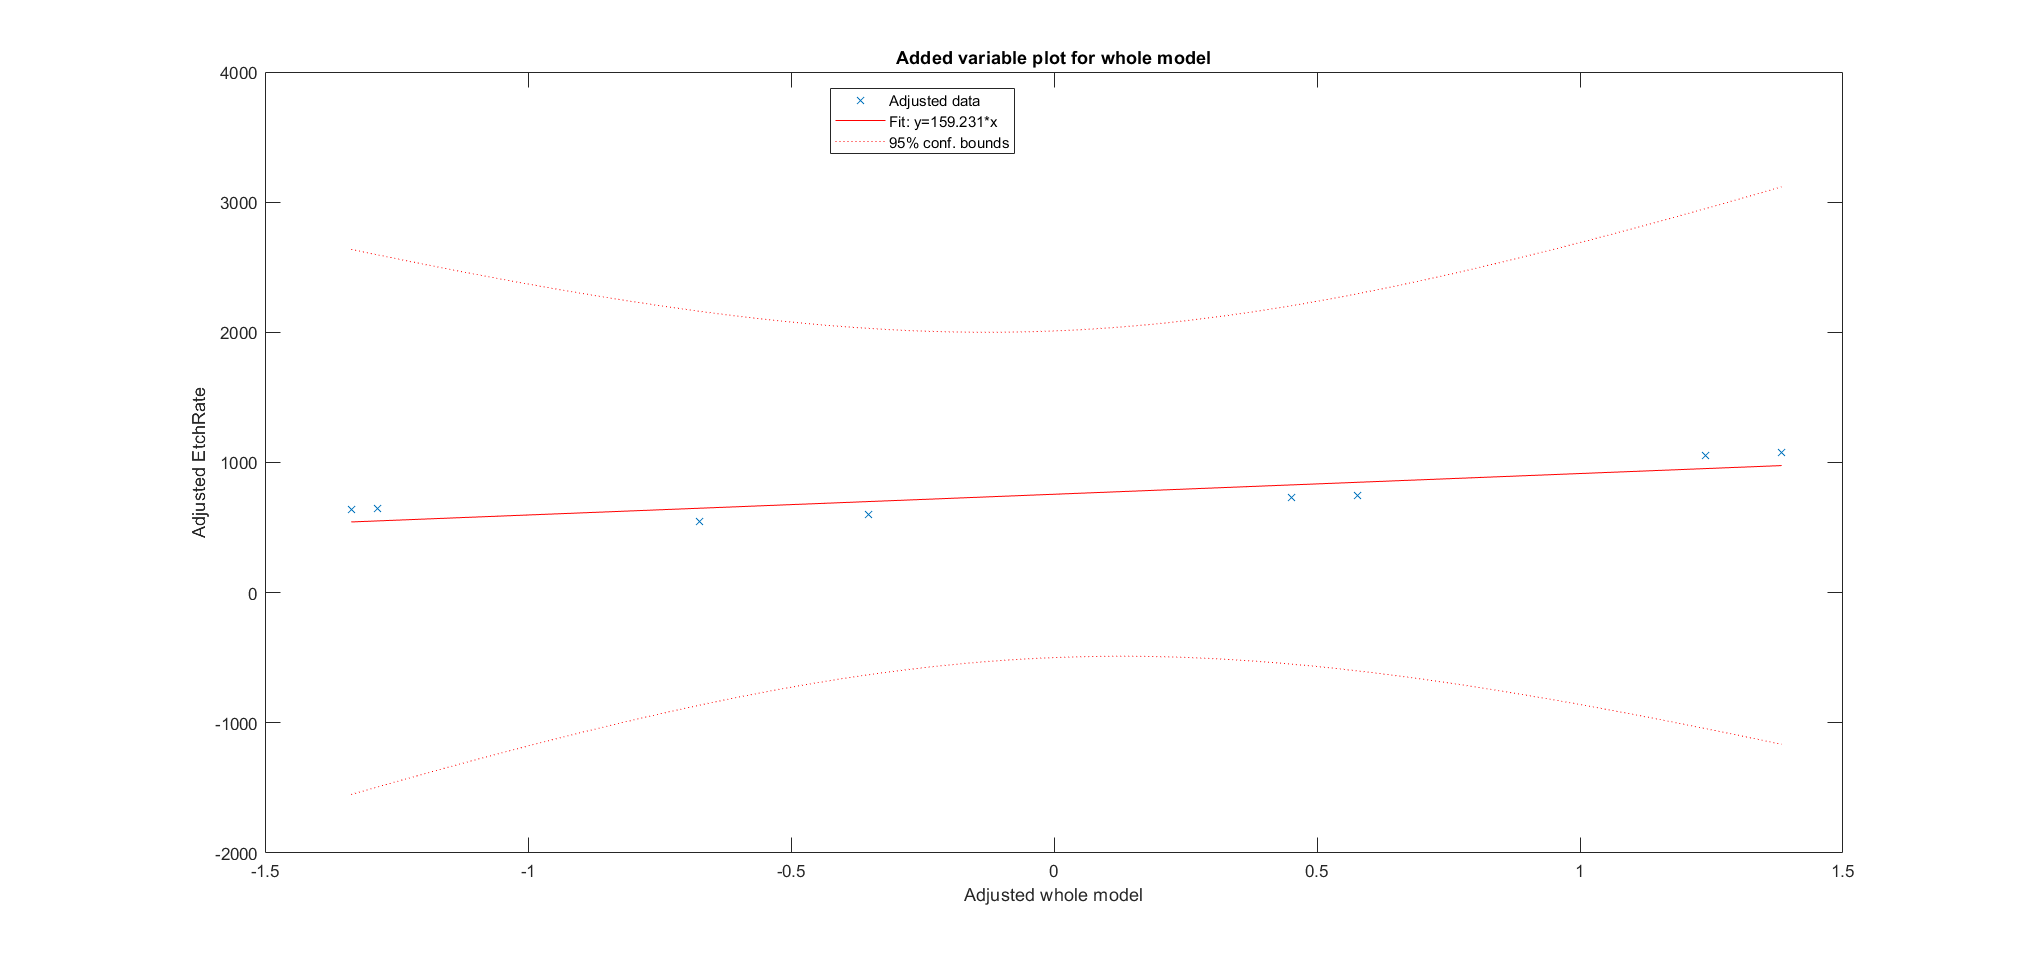

plot(mdl3)

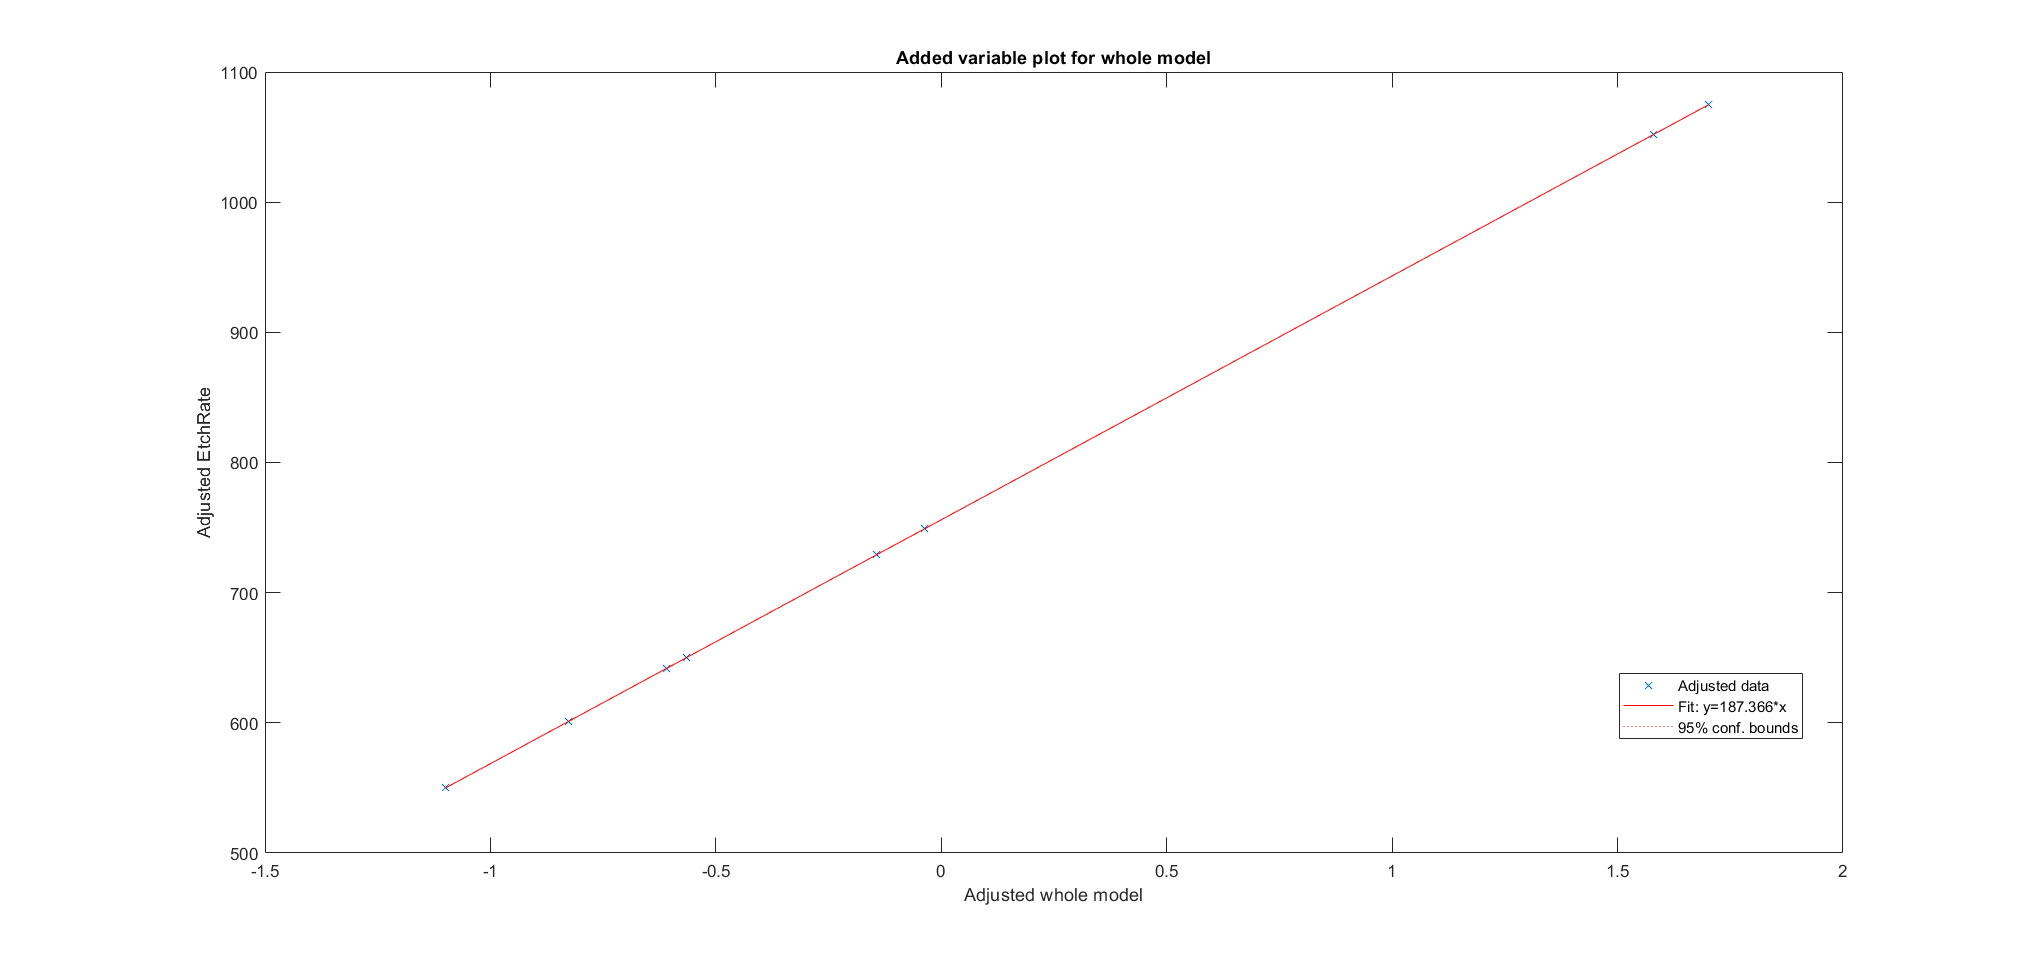

plot(mdl4) % Doesn't produce any stats, as there aren't any due to the singularity issue

f. Plot the probability plot of the effects

effects = mdl4.Coefficients.Estimate.*2; % Use dot notation to index into the 
% mdl4 structure, then multiply the regression coefficient x2 to obtain the
% factor effects
effects = effects(2:end) % Exclude the intercept value

effects =          -127
            4
         11.5
        290.5
          -10
        -25.5
       -197.5


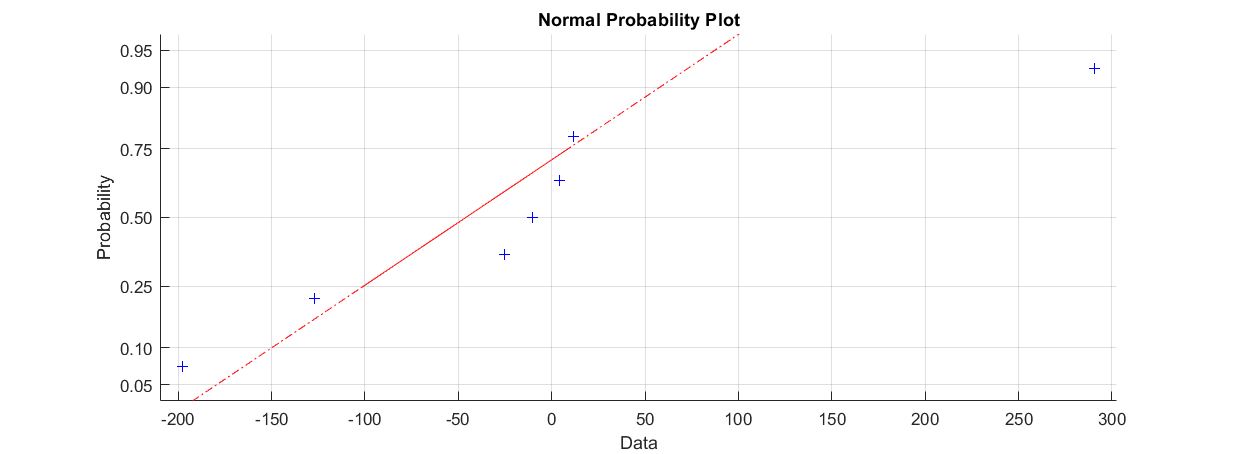

normplot(effects)

What does the normal probability plot of the effects tell us?

A normal probability plot is a "check" on the normality assumption. The probability assigned to each observation is based on the Z-score for that value. I.e., A probability value of .9242 translates to a Z-score of 1.4342, which means that there is an area to the left of this marker equal to 92.42% of the normal distribution bell curve. A resulting straight line indicates that the cumulative probabilities calculated from the data match the anticipated probabilities associated with the normal distribution. The observations should pass the "thick pencil test." (Montgomery, 2011, p.130)

Those effects that do not plot on the straight line, i.e., those that fail the "thick pencil test," are statistically significant factors.

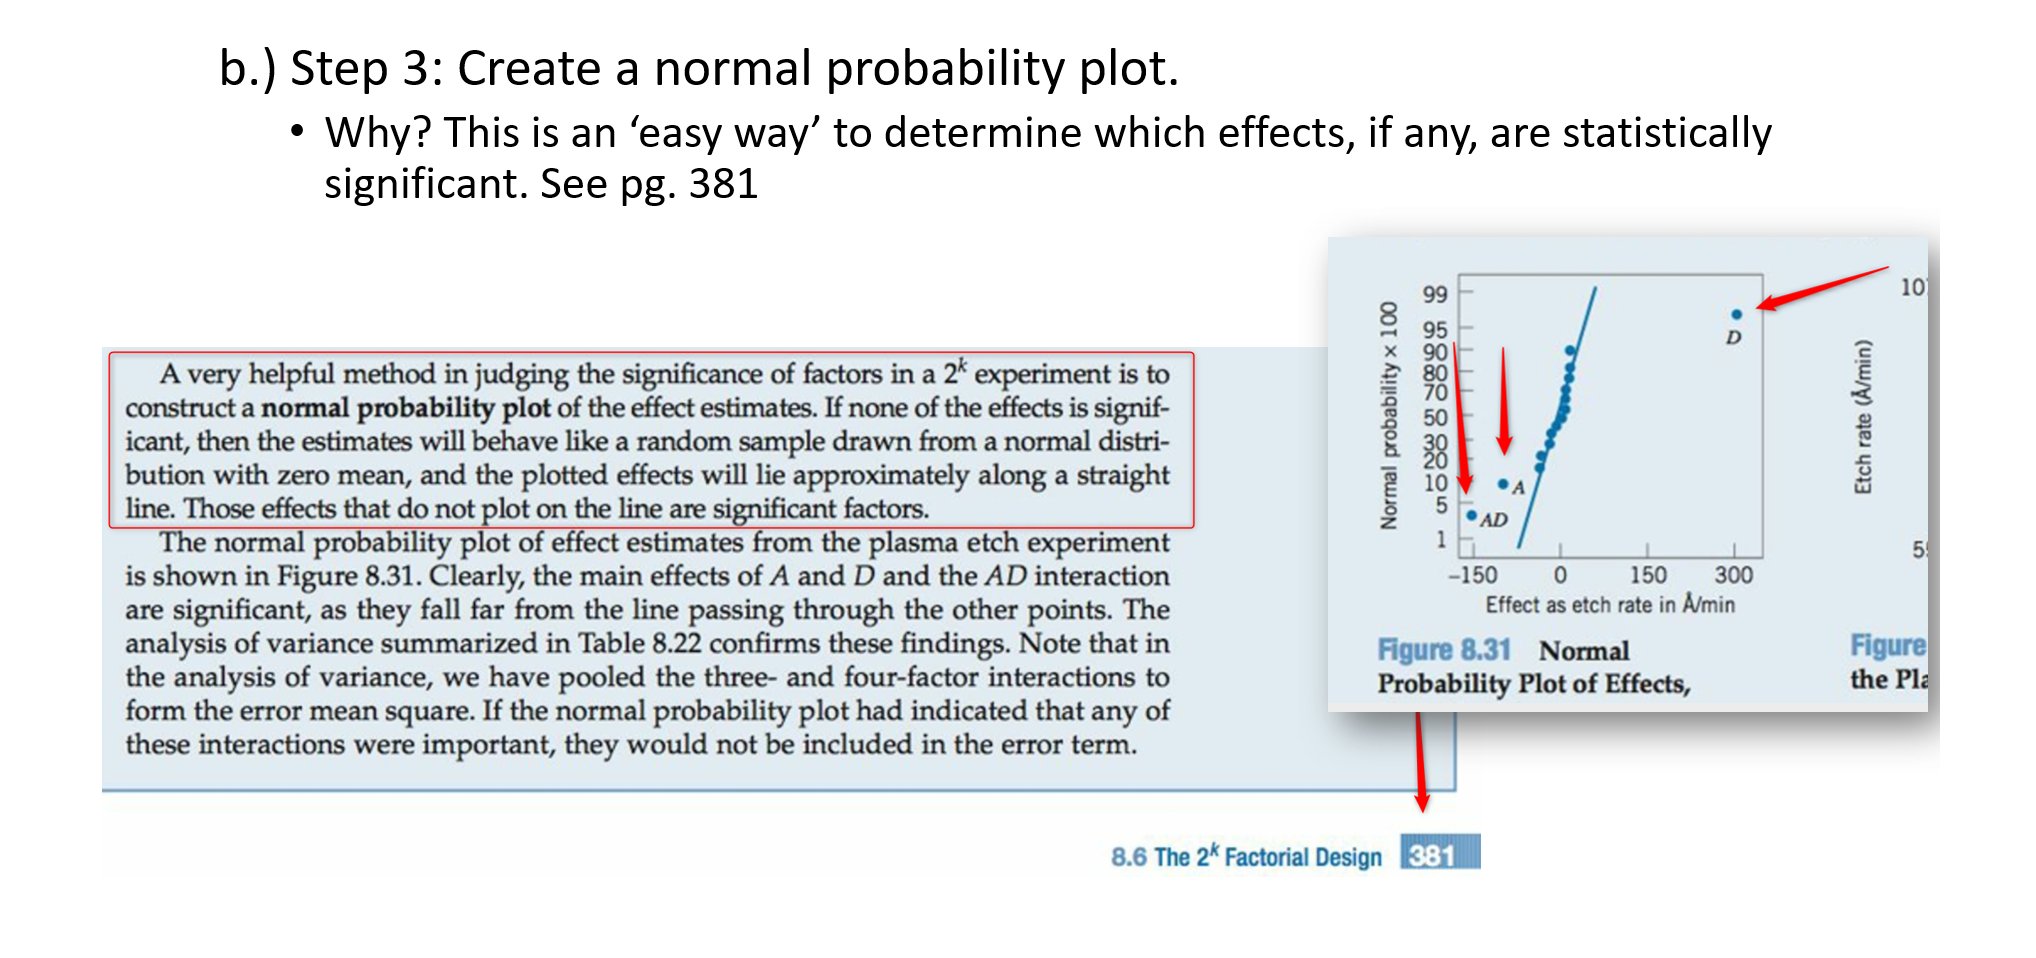

imshow('NormalProbEffects.png') % Background

Normal probability plot of effects conclusion:

Main effect D, and interaction terms AC, AD are infered to be statistically significant based on where they lie on the normal probability plot.

Does this coincide with the full-factorial results in Example 8.9?

f. Plot residuals 

Residuals help in checking model quality; these plots help in discovering errors, outliers, or correlations in the model or data.

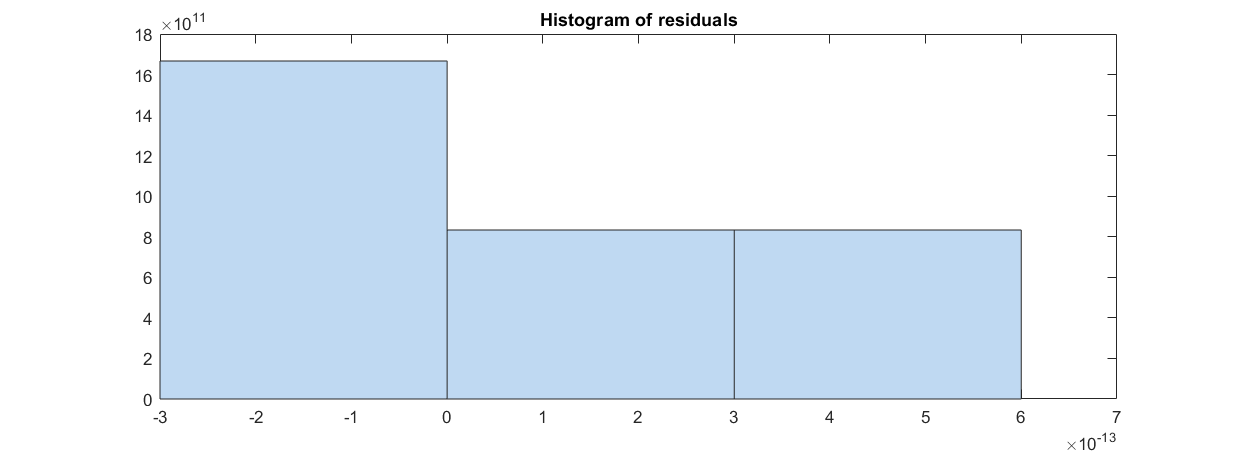

plotResiduals(mdl4)

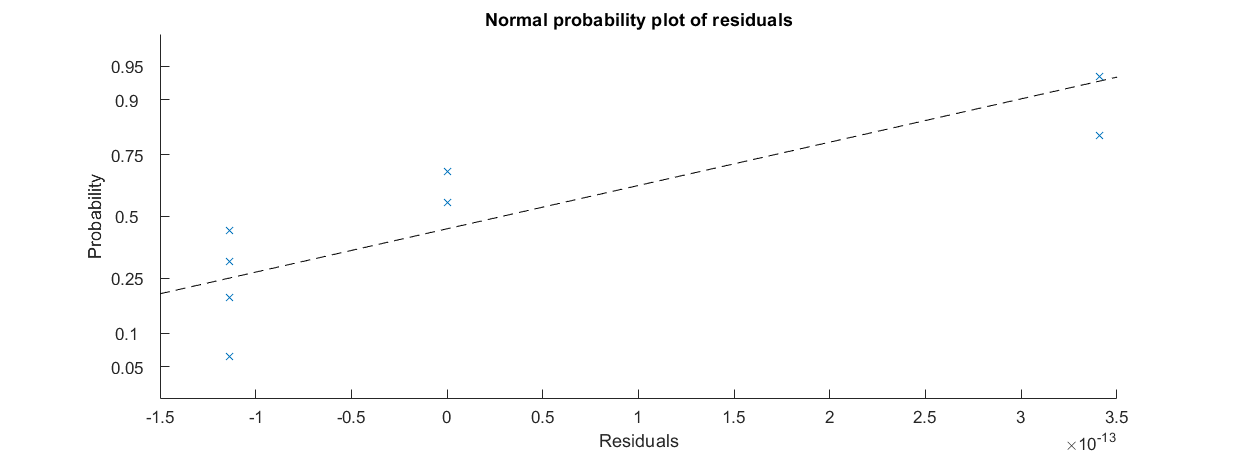

plotResiduals(mdl4,'probability')

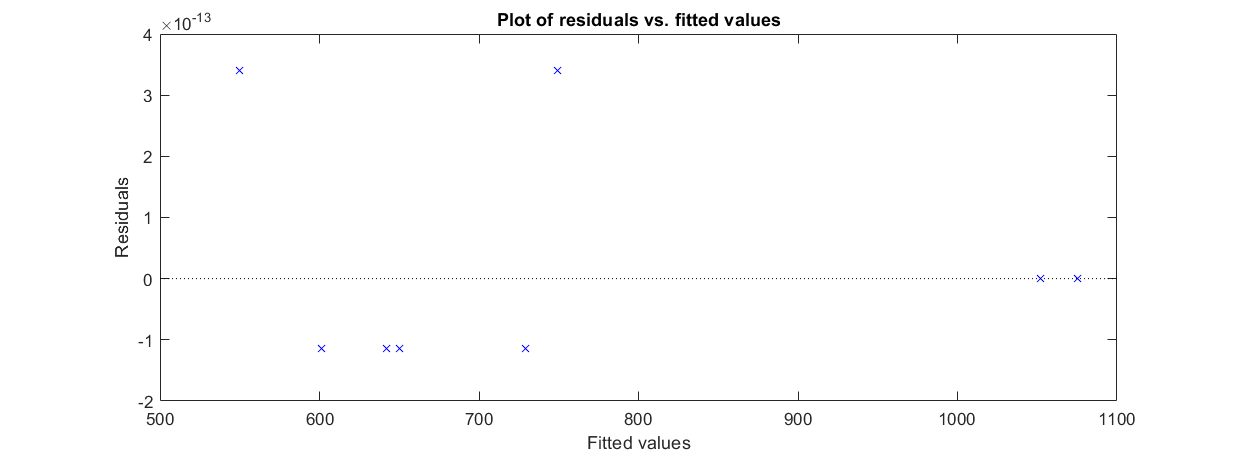

plotResiduals(mdl4,'fitted')

Residuals histogram plot: shows the range of the residuals and their frequencies. The area of each bar is the relative number of observations. The sum of the bar areas is equal to 1.

The generated histogram plot of the new model exhibits a skew to the left.

Normal probability plot of residuals shows how the distribution of the residuals compares to a normal distribution with matched variance. The probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals. 

- Small deviations from the straight line in a normal probability plot are common, but an “S” shaped curve on this graph suggests a bimodal distribution of residuals. *Breaks near the middle of this graph are also indications of abnormalities in the residual distribution.*

Plot of residuals vs. fitted values: The center-line is the fitted model and the data points are residuals. The spread among the residuals seems to be larger on the left par of design-space domain of the model, so we can conclude that the model is a poor fit of the data - more on the left hand side of the domain.

g. Considering only the statistically significant terms, we can re-design the test matrix into a full-factorial DOE; assign the response values accordingly, then perform the analysis.

[** not worked **]